
clear; clc; close all;

% top surface file:
%   Col 1: index
%   Col 2–17: pressure readings at 16 tappings (upper/near-LE)
% bottom surface file:
%   Col 1: index
%   Col 8–17: pressure readings at 10 tappings (lower surface)

top_data    = readtable('7062_860rpm_top_readings.csv','ReadVariableNames',false);
bottom_data = readtable('7062_860rpm_bottomreadings.csv','ReadVariableNames',false);

% get the pressure data
top_pressure_full    = table2array(top_data(:, 2:17));  % 16 columns
bottom_pressure_full = table2array(bottom_data(:, 8:17)); % 10 columns

n_upper = size(top_pressure_full,1);
n_lower = size(bottom_pressure_full,1);
n_meas  = min(n_upper, n_lower);

fprintf('Upper measurements available: %d\n', n_upper);

Upper measurements available: 150


fprintf('Lower measurements available: %d\n', n_lower);

Lower measurements available: 100


fprintf('Using first %d measurements.\n\n', n_meas);

Using first 100 measurements.




top_pressure    = top_pressure_full(1:n_meas,:);    % (n_meas x 16)
bottom_pressure = bottom_pressure_full(1:n_meas,:); % (n_meas x 10)

% DEFINE TAPPING POSITIONS ALONG CONTOUR

% Distances between consecutive tappings (mm) along the contour
distances_mm = [ ...
    7, 8, 8, 16, 15, 8, 8, 7, 7, 15, 15, 8, 8, 9, ...  % 1–15 (upper)
    35, ...                                            % 15–16 (LE gap)
    15, 15, 15, 15, 15, 15, 15, 15, 6 ];               % 16–25 (lower)

% Cumulative positions for tappings 1–25
pos_mm = [0, cumsum(distances_mm)];      % length 25
pos_norm = pos_mm / 100;                 % normalized by chord length

% mapping to chordwise x/c:
%   - Upper: tappings 1–15 go from TE (x/c≈1) to LE (x/c≈0).
%   - Lower: tappings 16–25 go from LE (x/c≈0) back to TE (x/c≈1).
x_c = zeros(1,25);

% Upper: use length up to LE (tap 16 position as reference)
LE_perim = pos_mm(16);   % position at LE gap (between 15 and 16)
for i = 1:15
    x_c(i) = 1 - pos_mm(i)/LE_perim;
end
x_c(16) = 0; % LE nominal

% Lower: map 16–25 from LE (0) to TE (1) using remaining perimeter
TE_perim = pos_mm(end);
for i = 17:25
    x_c(i) = (pos_mm(i) - pos_mm(16)) / (TE_perim - pos_mm(16));
end


% interpretation used:
%   - upper taps 1–15  → top_pressure(:,1:15)
%   - lower taps 16–25 → bottom_pressure(:,1:10)
%   => 15 + 10 = 25 taps
upper_press = top_pressure(:,1:15);     % n_meas x 15
lower_press = bottom_pressure(:,1:10);  % n_meas x 10

% add up to into n_meas x 25 matrix:
%   columns 1–15: upper (taps 1–15)
%   columns 16–25: lower (taps 16–25)
cp_mat = [upper_press, lower_press];    % size: (n_meas x 25)

fprintf('pressure matrix size: %d measurements x %d tappings\n\n', size(cp_mat,1), size(cp_mat,2));

pressure matrix size: 100 measurements x 25 tappings



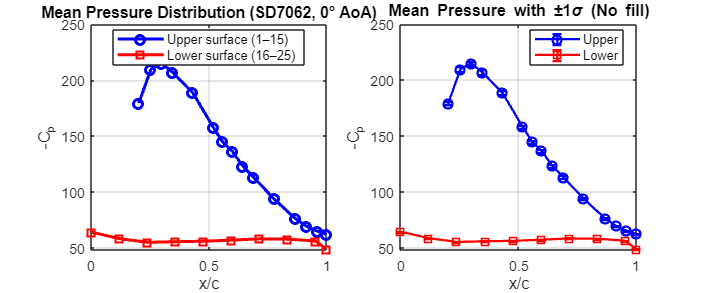


%% 4. BASIC STATISTICS (NO nanmean / nanstd)

mean_cp = mean(cp_mat, 1, 'omitnan');
std_cp  = std(cp_mat, 0, 1, 'omitnan');
min_cp  = min(cp_mat, [], 1);
max_cp  = max(cp_mat, [], 1);

% make things print neat

figure('Name','SD7062 Cp Distribution','Position',[100 100 1200 500]);

% Plot things-->
subplot(1,2,1);
%1st plot
subplot(1,2,1);
hold on; grid on; box on;
plot(x_c(1:15), -mean_cp(1:15), 'bo-','LineWidth',2,'MarkerSize',6);
plot(x_c(16:25), -mean_cp(16:25), 'rs-','LineWidth',2,'MarkerSize',6);
xlabel('x/c');
ylabel('-C_p');
title('Mean Pressure Distribution (SD7062, 0° AoA)');
legend({'Upper surface (1–15)','Lower surface (16–25)'},'Location','Best');

% 2nd plot
subplot(1,2,2);
hold on; grid on; box on;
errorbar(x_c(1:15), -mean_cp(1:15), std_cp(1:15), 'bo-','LineWidth',1.5,'MarkerSize',6);
errorbar(x_c(16:25), -mean_cp(16:25), std_cp(16:25), 'rs-','LineWidth',1.5,'MarkerSize',6);
% REMOVE this line:
% set(gca,'XDir','reverse');
xlabel('x/c');
ylabel('-C_p');
title('Mean Pressure with ±1\sigma (No fill)');
legend({'Upper','Lower'},'Location','Best');

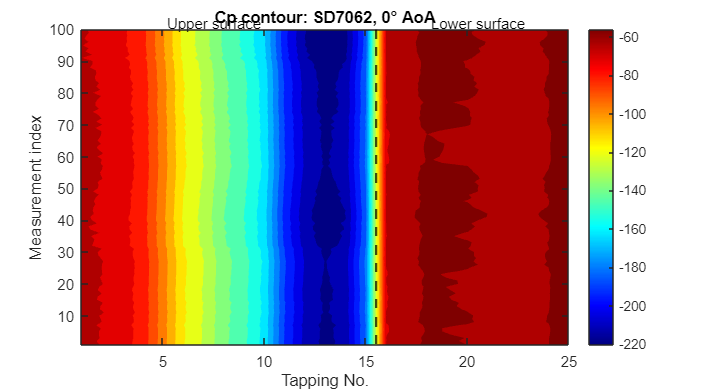



%cp plot

figure('Name','Cp contour','Position',[100 650 900 500]);
[Xtap,Ymeas] = meshgrid(1:25, 1:n_meas);
contourf(Xtap, Ymeas, cp_mat, 20, 'LineStyle','none');
colorbar;
xlabel('Tapping No.');
ylabel('Measurement index');
title('Cp contour: SD7062, 0° AoA');
colormap jet;
hold on;
xline(15.5,'k--','LineWidth',1.5);
text(7.5, n_meas*1.02, 'Upper surface','HorizontalAlignment','center');
text(20.5, n_meas*1.02,'Lower surface','HorizontalAlignment','center');
hold off;